clc
clear
close all

tic

% Definir os ângulos de ataque e os números de Reynolds
alpha = -180:1:180; % Intervalo de ângulos de ataque
Re = logspace(3, 9, 500); % Intervalo de Reynolds (escala logarítmica)

% Inicializar matriz para armazenar os resultados
conf_NeuralFoil = zeros(length(alpha), length(Re)); % Prealocar para melhorar o desempenho
% Loop para calcular os valores
for i = 1:length(alpha)
    for j = 1:length(Re)
        fprintf("-> Re = %.2e | AoA = %.2f\n", Re(j), alpha(i))
        % Chamada da função NeuralFoil
        [~, ~, conf_NeuralFoil(i, j)] = NeuralFoil("naca0012", Re(j), 0, alpha(i));
    end
end

-> Re = 1.00e+03 | AoA = -180.00


C:\Users\Utilizador\AppData\Local\Programs\Python\Python310\lib\site-packages\neuralfoil\gen2_5_architecture\main.py:13: RuntimeWarning: overflow encountered in exp
  return 1 / (1 + np.exp(-x))


-> Re = 1.03e+03 | AoA = -180.00
-> Re = 1.06e+03 | AoA = -180.00
-> Re = 1.09e+03 | AoA = -180.00
-> Re = 1.12e+03 | AoA = -180.00
-> Re = 1.15e+03 | AoA = -180.00
-> Re = 1.18e+03 | AoA = -180.00
-> Re = 1.21e+03 | AoA = -180.00
-> Re = 1.25e+03 | AoA = -180.00
-> Re = 1.28e+03 | AoA = -180.00
-> Re = 1.32e+03 | AoA = -180.00
-> Re = 1.36e+03 | AoA = -180.00
-> Re = 1.39e+03 | AoA = -180.00
-> Re = 1.43e+03 | AoA = -180.00
-> Re = 1.47e+03 | AoA = -180.00
-> Re = 1.51e+03 | AoA = -180.00
-> Re = 1.56e+03 | AoA = -180.00
-> Re = 1.60e+03 | AoA = -180.00
-> Re = 1.65e+03 | AoA = -180.00
-> Re = 1.69e+03 | AoA = -180.00
-> Re = 1.74e+03 | AoA = -180.00
-> Re = 1.79e+03 | AoA = -180.00
-> Re = 1.84e+03 | AoA = -180.00
-> Re = 1.89e+03 | AoA = -180.00
-> Re = 1.94e+03 | AoA = -180.00
-> Re = 2.00e+03 | AoA = -180.00
-> Re = 2.05e+03 | AoA = -180.00
-> Re = 2.11e+03 | AoA = -180.00
-> Re = 2.17e+03 | AoA = -180.00
-> Re = 2.23e+03 | AoA = -180.00
-> Re = 2.29e+03 | AoA = -180.00
-> Re = 2.


%% Gráficos 3D e 2D
close all

% Criar o gráfico 3D
figure()
[X, Y] = meshgrid(Re, alpha); % Criar malha para o gráfico
surf(X, Y, conf_NeuralFoil, 'EdgeColor', 'none') % Gráfico de superfície
c = colorbar; % Barra de cores
shading interp % Suavizar os contornos
colormap jet; % Escolher esquema de cores
ylabel(c, "Confidence Level") % Adicionar legenda

% Adicionar plano em z = 0.9
hold on
Z_plane = 0.9 * ones(size(X)); % Matriz para o plano em z = 0.9
surf(X, Y, Z_plane, 'FaceAlpha', 0.3, 'EdgeColor', 'none', 'FaceColor', 'black') % Plano transparente
hold off

% Ajustar aparência do gráfico
set(gca, 'XScale', 'log') % Escala logarítmica no eixo X
xlabel('Re')
ylabel('\alpha (degrees)')
zlabel('H')
title('Neural Foil Confidence')
grid on

saveas(gcf, './studies/neuralfoil_confidence/NeuralFoil_Confidence_Plot_3D.png') % Salvar como arquivo PNG

% Criar o gráfico 2D
figure()
[X, Y] = meshgrid(alpha, Re); % Criar malha para o gráfico (alpha no X, Re no Y)
pcolor(X', Y', conf_NeuralFoil) % Gráfico colorido 2D (transpor para alinhar corretamente)
shading interp % Suavizar os contornos
c = colorbar; % Barra de cores
colormap jet; % Escolher esquema de cores
ylabel(c, "Confidence Level") % Adicionar legenda

% Ajustar aparência do gráfico
set(gca, 'YScale', 'log') % Escala logarítmica no eixo Y
xlabel('\alpha (degrees)')
ylabel('Re')
title('Neural Foil Confidence')
grid on

% Salvar como arquivo PNG
saveas(gcf, './studies/neuralfoil_confidence/NeuralFoil_Confidence_2D.png')

% GRÁFICOS A PRETO E BRANCO

% Criar o gráfico 3D
figure()
[X, Y] = meshgrid(Re, alpha); % Criar malha para o gráfico
surf(X, Y, conf_NeuralFoil, 'EdgeColor', 'none') % Gráfico de superfície
c = colorbar; % Barra de cores
shading interp % Suavizar os contornos
colormap(flipud(gray)); % Escolher esquema de cores em preto e branco
ylabel(c, "Confidence Level") % Adicionar legenda

% Adicionar plano em z = 0.9
hold on
Z_plane = 0.9 * ones(size(X)); % Matriz para o plano em z = 0.9
surf(X, Y, Z_plane, 'FaceAlpha', 0.3, 'EdgeColor', 'none', 'FaceColor', 'red') % Plano transparente
hold off

% Ajustar aparência do gráfico
set(gca, 'XScale', 'log') % Escala logarítmica no eixo X
xlabel('Re')
ylabel('\alpha (degrees)')
zlabel('H')
title('Neural Foil Confidence')
grid on

saveas(gcf, './studies/neuralfoil_confidence/NeuralFoil_Confidence_Plot_3D_black.png') % Salvar como arquivo PNG

%%

% Create the 2D color plot
figure()

[X, Y] = meshgrid(alpha, Re); % Create mesh for the plot (alpha on X, Re on Y)
pcolor(X', Y', conf_NeuralFoil) % 2D colored plot (transpose to align correctly)
shading interp % Smooth the contours

% Add colorbar with label
c = colorbar; % Add colorbar
c.Label.String = 'Confidence Level'; % Set colorbar label
c.Location = 'eastoutside'; % Place the colorbar outside the plot on the right

% Adjust colormap to grayscale
colormap(flipud(gray)); % Choose black-and-white color scheme

% Adjust plot appearance
set(gca, 'YScale', 'log') % Logarithmic scale on Y-axis
xlabel('\alpha (degrees)')
ylabel('Re')
title('Neural Foil Confidence')
grid on

% Save as PNG file
saveas(gcf, './studies/neuralfoil_confidence/NeuralFoil_Confidence_2D_black.png')



%%
elapsedTime = toc; % Tempo decorrido em segundos

% Converter para horas, minutos e segundos
hours = floor(elapsedTime / 3600);
minutes = floor(mod(elapsedTime, 3600) / 60);
seconds = mod(elapsedTime, 60);

% Exibir no formato HH:MM:SS, arredondando os segundos
fprintf("\n\n-> Time elapsed = %02d:%02d:%02d\n", hours, minutes, round(seconds));


#### Curvas de confiança

clc
clear
close all
Re = [1e4 1e5 1e6];
alpha = -180:1:180;

cl = zeros(length(Re), length(alpha));
cd = zeros(length(Re), length(alpha));
conf = zeros(length(Re), length(alpha));


for i = 1:length(Re)
    for j = 1:length(alpha)
        [cl(i, j), cd(i, j), ~, conf(i, j)] = NeuralFoil("naca0012", Re(i), 0, alpha(j));
    end
end

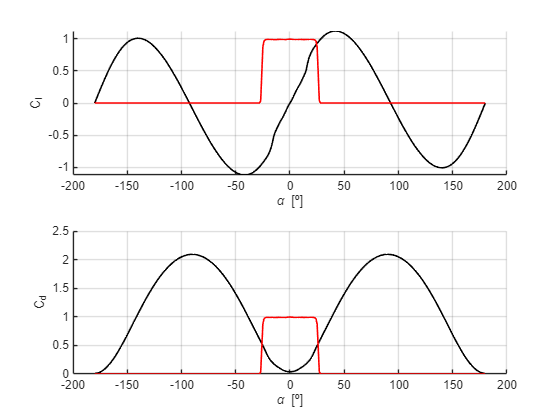

figure()

subplot(2, 1, 1)
hold on
plot(alpha, cl(1, :), 'k', 'LineWidth', 1.2)  % C_l em preto
plot(alpha, conf(1, :), 'r', 'LineWidth', 1.2) % conf em vermelho
xlabel('\alpha [º]')
ylabel('C_l | Re')
hold off
grid on

subplot(2, 1, 2)
hold on
plot(alpha, cd(1, :), 'k', 'LineWidth', 1.2)  % C_d em preto
plot(alpha, conf(1, :), 'r', 'LineWidth', 1.2)
xlabel('\alpha [º]')
ylabel('C_d | Re')
hold off
grid on
saveas(gcf, ".\studies\neuralfoil_confidence\aero_model_1e4", 'epsc'); 

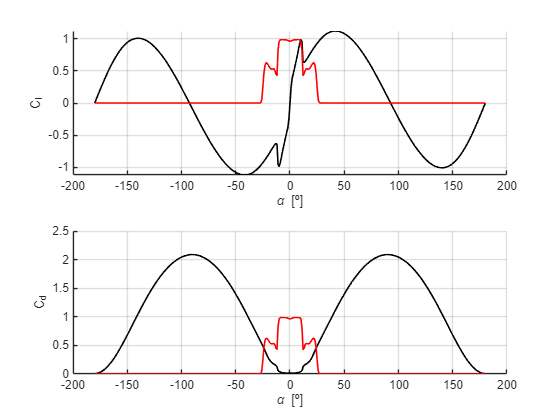

figure()

subplot(2, 1, 1)
hold on
plot(alpha, cl(2, :), 'k', 'LineWidth', 1.2)  % C_l em preto
plot(alpha, conf(2, :), 'r', 'LineWidth', 1.2) % conf em vermelho
xlabel('\alpha [º]')
ylabel('C_l | Re')
hold off
grid on

subplot(2, 1, 2)
hold on
plot(alpha, cd(2, :), 'k', 'LineWidth', 1.2)  % C_d em preto
plot(alpha, conf(2, :), 'r', 'LineWidth', 1.2)
xlabel('\alpha [º]')
ylabel('C_d | Re')
hold off
grid on
saveas(gcf, ".\studies\neuralfoil_confidence\aero_model_1e5", 'epsc'); 

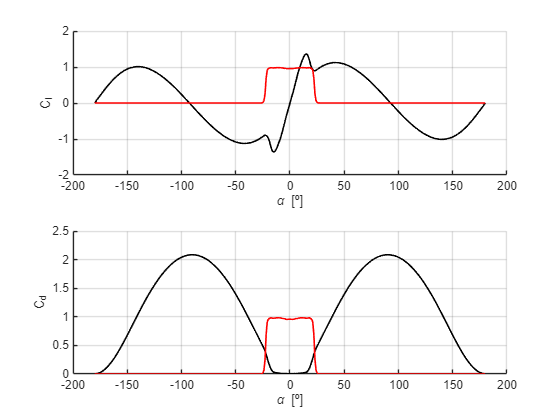

figure()

subplot(2, 1, 1)
hold on
plot(alpha, cl(3, :), 'k', 'LineWidth', 1.2)
plot(alpha, conf(3, :), 'r', 'LineWidth', 1.2)
xlabel('\alpha [º]')
ylabel('C_l | Re')
hold off
grid on

subplot(2, 1, 2)
hold on
plot(alpha, cd(3, :), 'k', 'LineWidth', 1.2) % Aqui troquei cd(1, :) por cd(2, :) para corresponder a Re = 1e6
plot(alpha, conf(3, :), 'r', 'LineWidth', 1.2)
xlabel('\alpha [º]')
ylabel('C_d | Re')
hold off
grid on

hold off;
saveas(gcf, ".\studies\neuralfoil_confidence\aero_model_1e6", 'epsc'); 